# **CONTROL AUTOMÁTICO**

# FINAL

***Profesor: Ricardo Vecchio***

***Alumna: Trinidad Burs***

***Fecha: 10/02/2021***

G = tf( [0.5], [1 1] );
C = zpk( [-1], [0], 4.3 ); %-->se obtiene con sisotool
H = tf( [1], [1] );
%sisotool(G,C,H)

[numG,denG]=tfdata(G,'v');
[numH,denH]=tfdata(H,'v');
[numC,denC]=tfdata(C,'v');

Ts=0.017; %seg --> rise_time/60
[numCd,denCd] = c2dm(numC,denC,Ts,'zoh');

***Graficos***

datos_A = xlsread('C:\Users\Trini\Documents\UCA\5° Año\Segundo Cuatrimestre\Control Automatico\FINAL\valores.xlsx',1);
datos_B = xlsread('C:\Users\Trini\Documents\UCA\5° Año\Segundo Cuatrimestre\Control Automatico\FINAL\valores.xlsx',2);
datos_C = xlsread('C:\Users\Trini\Documents\UCA\5° Año\Segundo Cuatrimestre\Control Automatico\FINAL\valores.xlsx',3);

En el codigo de MPLAB el primer datos que se imprime siempre es cero (para asegurarme que todo este en reposo) pero el sistema empieza a tener sentido recien en el dato que le sigue porque recien ahi estoy teniendo en cuenta la entrada, por esta razon hare lo siguiente:

%Con estas lineas de codigo elimino el primer valor
datos_A(1) = [];
datos_B(1) = [];
datos_C(1) = [];

Estos datos representan el resultado de la conversion del AD (en modo 8 bits), si quiero ver cuanto representan en volts debo hacer la siguiente conversion

datos_A = datos_A * 5 / 255;
datos_B = datos_B * 5 / 255;
datos_C = datos_C * 5 / 255;

En el caso de los datos A y B sabemos que el intervalo de mustreo utilizado es 0,017 seg; por el contrario para los datos C este intervalo no sera constante. Aunque el tiempo de adquisicion si lo es (20 Tad), como ya demostramos usando el TMR1 el tiempo de la ruitna varia. Debido a esto el eje x para este grafico se expresara en numero de muestras y no en tiempo.

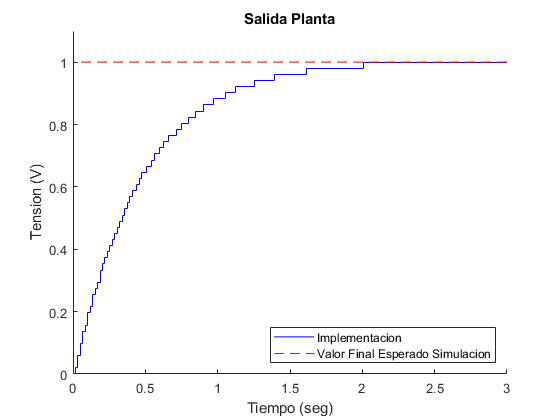

Ts=0.017;
N_muestra = 0:1:(max(size(datos_A))-1);
t_muestra = N_muestra * Ts;

figure(1)
hold on
stairs(t_muestra,datos_A,'b')
plot([0 t_muestra(end)],[1 1],'--r')
title('Salida Planta')
ylabel('Tension (V)')
xlabel('Tiempo (seg)')
xlim([0 3])
ylim([0 1.1])
legend({'Implementacion','Valor Final Esperado Simulacion'},'Location','southeast')
hold off

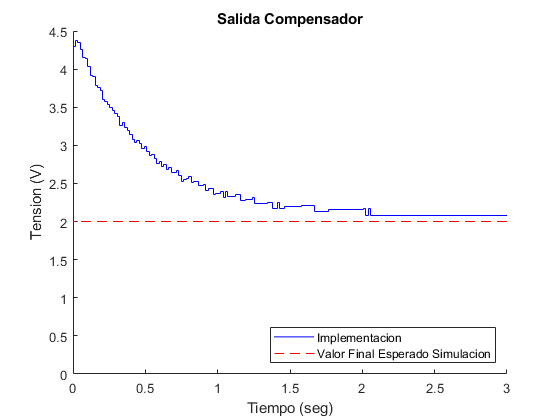


figure(2)
hold on
stairs(t_muestra,datos_B,'b')
plot([0 t_muestra(end)],[2 2],'--r')
title('Salida Compensador')
ylabel('Tension (V)')
xlabel('Tiempo (seg)')
xlim([0 3])
ylim([0 4.5])
legend({'Implementacion','Valor Final Esperado Simulacion'},'Location','southeast')
hold off

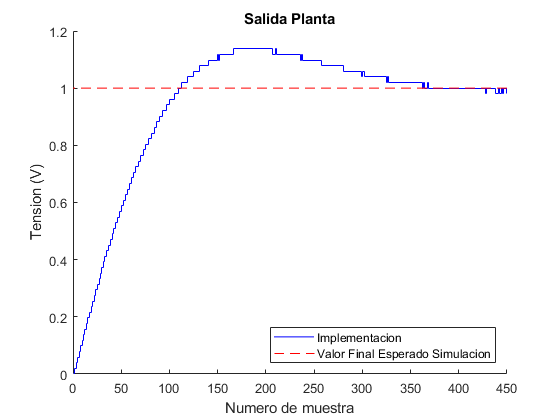


figure(3)
hold on
stairs(N_muestra,datos_C,'b')
plot([0 N_muestra(end)],[1 1],'--r')
title('Salida Planta')
ylabel('Tension (V)')
xlabel('Numero de muestra')
xlim([0 450])
ylim([0 1.2])
legend({'Implementacion','Valor Final Esperado Simulacion'},'Location','southeast')
hold off

Sera interesante comparar el primer grafico con el que obtenemos utilizando sisotool. Antes de correr las siguientes lineas asegurarse de tener en el workspace "graphSisotool"

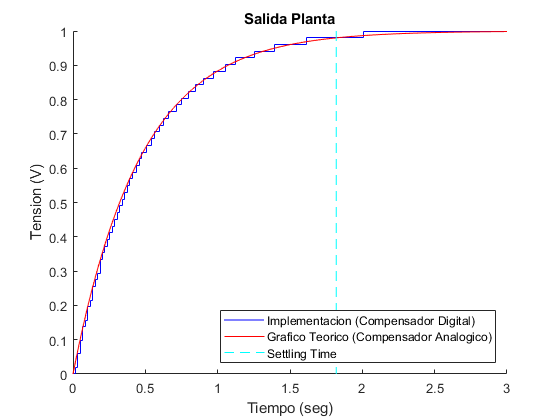

x_C=get(graphSisotool,'Xdata');
y_C=get(graphSisotool,'Ydata');
x_C=x_C{3};
y_C=y_C{3};
x_C(end)=[];
y_C(end)=[];

figure(4)
hold on
stairs(t_muestra,datos_A,'b')
plot(x_C,y_C,'r')
plot([1.82 1.82],[0 5],'--c')
title('Salida Planta')
ylabel('Tension (V)')
xlabel('Tiempo (seg)')
xlim([0 3])
ylim([0 1])
legend({'Implementacion (Compensador Digital)','Grafico Teorico (Compensador Analogico)','Settling Time'},'Location','southeast')
hold off

Si queremos comparar la salida real del compensador con la salida del compensador de la simulacion lo podemos hacer utilizando un bloque que convierte los graficos de mi simulink en un archivo '.mat'. En la simulacion este bloque esta desactivado (se provee el archivo Out_C_Dig para cargar directamente al workspace).

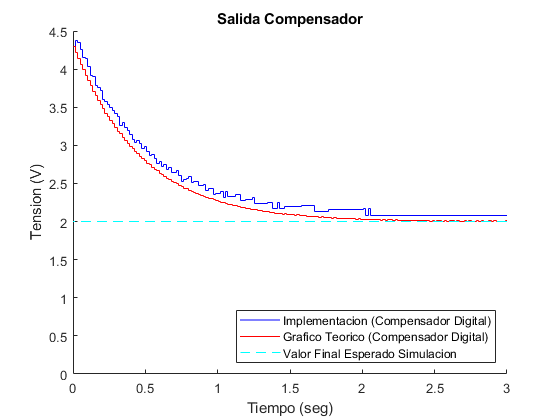

figure(5)
hold on
stairs(t_muestra,datos_B,'b')
stairs(Out_C_Dig(1,:),Out_C_Dig(2,:),'r')
plot([0 t_muestra(end)],[2 2],'--c')
title('Salida Compensador')
ylabel('Tension (V)')
xlabel('Tiempo (seg)')
xlim([0 3])
ylim([0 4.5])
legend({'Implementacion (Compensador Digital)','Grafico Teorico (Compensador Digital)','Valor Final Esperado Simulacion'},'Location','southeast')
hold off